clear
clc

a = 1:10;
b = 'stybn';
c = [1 1 2; 2 3 4];
who


您的变量为:

a  b  c  



whos

  Name      Size            Bytes  Class     Attributes

  a         1x10               80  double              
  b         1x5                10  char                
  c         2x3                48  double              




save a

clear
load a
who


您的变量为:

a  b  c  



whos

  Name      Size            Bytes  Class     Attributes

  a         1x10               80  double              
  b         1x5                10  char                
  c         2x3                48  double              



# *** 实验一．MATLAB 语言基础***

## 一．MATLAB 的基本计算功能

## 例1.1.1：用Matlab 显示430/12的不同显示结果


clear
clc
430/12

ans = 35.8333

format short
430/12

ans = 35.8333


format long
430/12

ans =   35.833333333333336



format short e
430/12

ans =    3.5833e+01



format long e
430/12

ans =      3.583333333333334e+01



format hex
430/12

ans =    4041eaaaaaaaaaab



format bank
430/12

ans =          35.83



format +
430/12

ans = +



format rat
430/12

ans =      215/6     


## 二．MATLAB 矩阵和数组的创建和保存

## 例1.2.1：用指令产生数值矩阵


clear
clc
format short

A = [];
x = 9;
y = pi/6;
A = [3 5 sin(y);cos(y) x^2 7;x/2 5 1]

A =     3.0000    5.0000    0.5000
    0.8660   81.0000    7.0000
    4.5000    5.0000    1.0000


## 例1.2.2：矩阵元素的修改


A(3,3) = 0

A =     3.0000    5.0000    0.5000
    0.8660   81.0000    7.0000
    4.5000    5.0000         0


A(2,6) = 1

A =     3.0000    5.0000    0.5000         0         0         0
    0.8660   81.0000    7.0000         0         0    1.0000
    4.5000    5.0000         0         0         0         0


## 例1.2.3：复数矩阵的建立和输入


a = 2.7;
b = 13/25;
C = [1 2*a+i*b b*sqrt(a);sin(pi/4) a+5*b 3.5+1]

C =    1.0000 + 0.0000i   5.4000 + 0.5200i   0.8544 + 0.0000i
   0.7071 + 0.0000i   5.3000 + 0.0000i   4.5000 + 0.0000i



R = [1 2 3 ;4 5 6];
M = [11 12 13 ;14 15 16];
CN = R+i*M

CN =    1.0000 +11.0000i   2.0000 +12.0000i   3.0000 +13.0000i
   4.0000 +14.0000i   5.0000 +15.0000i   6.0000 +16.0000i


## 例1.2.4：符号矩阵的生成


a11 = 'a';
a12 = 'b';
a13 = 'c';
a21 = 'Jack';
a22 = 'Help Me!';
a23 = 'No Way!';
sym_matrix = str2sym('[a, b, c;Jack,HelpMe,NoWay ]')

$$sym\_matrix = \left(\begin{array}{ccc} a & b & c\\ \mathrm{Jack} & \mathrm{HelpMe} & \mathrm{NoWay} \end{array}\right)$$


help sym

sym - Create symbolic variables, expressions, functions, matrices

    This MATLAB function creates symbolic variable x.

    x = sym('x')
    A = sym('a',[n1 ... nM])
    A = sym('a',n)
    sym(___,set)
    sym(___,'clear')
    sym(num)
    sym(num,flag)
    sym(strnum)
    symexpr = sym(h)

    另请参阅 <a href="https://localhost:31515/static/help/symbolic/assume.html">assume</a>, <a href="https://localhost:31515/static/help/symbolic/double.html">double</a>, <a href="https://localhost:31515/static/help/symbolic/reset.html">reset</a>, <a href="https://localhost:31515/static/help/symbolic/str2sym.html">str2sym</a>, <a href="https://localhost:31515/static/help/symbolic/symfun.html">symfun</a>, <a href="https://localhost:31515/static/help/symbolic/syms.html">syms</a>, <a href="https://localhost:31515/static/help/symbolic/symvar.html">symvar</a>

    sym 的文档
    <a href="matlab:matlab.internal.language.introspective.overloads.displayOverloads('sym')">名为 sym 的其他函数<

% sym1 = str2sym('[a,b,c;a21,a22,a23]')
% sym2 = sym([a11,a12,a13;a21,a22,a23])

sym_digits = str2sym('[1 2 3;a b c;sin(x) cos(y) tan(z)]')

$$sym\_digits = \left(\begin{array}{ccc} 1 & 2 & 3\\ a & b & c\\ \sin\left(x\right) & \cos\left(y\right) & \tan\left(z\right) \end{array}\right)$$


syms a b c;
M1 = sym('Classical');
M2 = sym('Jazz');
M3 = sym('Blues');
syms_matrix = [a b c;M1 M2 M3;2 3 5]

$$syms\_matrix = \left(\begin{array}{ccc} a & b & c\\ \mathrm{Classical} & \mathrm{Jazz} & \mathrm{Blues}\\ 2 & 3 & 5 \end{array}\right)$$


Dight_Matrix = [1/3 sqrt(2) 3.4234;exp(0.23) log(29) 23^(-11.23)]

Dight_Matrix =     0.3333    1.4142    3.4234
    1.2586    3.3673    0.0000


Syms_Matrix = sym(Dight_Matrix)

$$Syms\_Matrix = \left(\begin{array}{ccc} \frac{1}{3} & \sqrt{2} & \frac{17117}{5000}\\ \frac{5668230535726899}{4503599627370496} & \frac{7582476122586655}{2251799813685248} & \frac{5174709270083729}{10141204801825835211973625643008} \end{array}\right)$$

## 例1.2.5：大矩阵的生成


example;

exm =          456         468         873           2         579          55
          21         687          54         488           8          13
          65        4567          88          98          21           5
         456          68        4589         654           5         987
        5488          10           9           6          33          77


size(exm)

ans =      5     6


## 例1.2.6：多维数组的创建


A1 = [1 2 3 ;4 5 6 ;7 8 9];
A2 = A1';
A3=A1-A2;
A4(:,:,1) = A1;
A4(:,:,2) = A2;
A4(:,:,3) = A3;
A4

A4 = A4(:,:,1) =

     1     2     3
     4     5     6
     7     8     9


A4(:,:,2) =

     1     4     7
     2     5     8
     3     6     9


A4(:,:,3) =

     0    -2    -4
     2     0    -2
     4     2     0



A5 = cat(3,A1,A2,A3)

A5 = A5(:,:,1) =

     1     2     3
     4     5     6
     7     8     9


A5(:,:,2) =

     1     4     7
     2     5     8
     3     6     9


A5(:,:,3) =

     0    -2    -4
     2     0    -2
     4     2     0


A6 = cat(2,A1,A2,A3)

A6 =      1     2     3     1     4     7     0    -2    -4
     4     5     6     2     5     8     2     0    -2
     7     8     9     3     6     9     4     2     0


A7 = cat(1,A1,A2,A3)

A7 =      1     2     3
     4     5     6
     7     8     9
     1     4     7
     2     5     8
     3     6     9
     0    -2    -4
     2     0    -2
     4     2     0



size(A)

ans =      3     6


size(A4)

ans =      3     3     3


## 例1.2.7：产生一个3×4随机矩阵


R = rand(3,4)

R =     0.2511    0.3517    0.5497    0.7572
    0.6160    0.8308    0.9172    0.7537
    0.4733    0.5853    0.2858    0.3804


## 例1.2.8：产生一个在区间[10, 20]内均匀分布的4阶随机矩阵


a = 10;
b = 20;
x = a+(b-a)*rand(4)

x =    15.6782   17.7917   14.6939   17.9428
   10.7585   19.3401   10.1190   13.1122
   10.5395   11.2991   13.3712   15.2853
   15.3080   15.6882   11.6218   11.6565


## 例1.2.9：产生均值为0.6，方差为0.1的4阶矩阵


mu = 0.6;
sigma = 0.1;
x = mu + sqrt(sigma)*randn(4)

x =     0.6960    1.1413    1.0284    1.0543
    0.4102    0.5386    0.2610   -0.0201
    0.7549   -0.0762    0.9039    0.5375
    0.8338    0.3345    0.6392    0.2180


## 例1.2.10：用rand 函数可以产生任意行列的0～1 分布的随机矩阵


ra = rand(2,4)

ra =     0.9619    0.7749    0.8687    0.3998
    0.0046    0.8173    0.0844    0.2599


## 例1.2.11：利用diag 函数产生对角阵


a = randn(5,5)

a =     1.0984   -0.8236   -1.3337   -0.2620   -1.1564
   -0.2779   -1.5771    1.1275   -1.7502   -0.5336
    0.7015    0.5080    0.3502   -0.2857   -2.0026
   -2.0518    0.2820   -0.2991   -0.8314    0.9642
   -0.3538    0.0335    0.0229   -0.9792    0.5201


d = diag(a)

d =     1.0984
   -1.5771
    0.3502
   -0.8314
    0.5201


D = diag(d)

D =     1.0984         0         0         0         0
         0   -1.5771         0         0         0
         0         0    0.3502         0         0
         0         0         0   -0.8314         0
         0         0         0         0    0.5201


## 例1.2.12：提取矩阵的子阵

B = magic(5)

B =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


B1 = B(1:2,[1 3 5])

B1 =     17     1    15
    23     7    16


B2 = B([3,1],:)

B2 =      4     6    13    20    22
    17    24     1     8    15


B([1,3],[2,4])=zeros(2)

B =     17     0     1     0    15
    23     5     7    14    16
     4     0    13     0    22
    10    12    19    21     3
    11    18    25     2     9


L = B(1,:)<5

L = 1×5 logical 数组
   0   1   1   1   0


B = B(1,L)

B =      0     1     0


## 例1.2.13：矩阵的旋转和转置的区别


A = [1 2 3 4;5 6 7 8;9 10 11 12];
B1 = rot90(A)

B1 =      4     8    12
     3     7    11
     2     6    10
     1     5     9


BT = A'

BT =      1     5     9
     2     6    10
     3     7    11
     4     8    12


B2 = rot90(A,2)

B2 =     12    11    10     9
     8     7     6     5
     4     3     2     1


## 例1.2.14：矩阵的变维


B = reshape(A,2,6)

B =      1     9     6     3    11     8
     5     2    10     7     4    12


## 例1.2.15：部分元素的截取


LA = tril(A,-1)

LA =      0     0     0     0
     5     0     0     0
     9    10     0     0


UA = triu(A,1)

UA =      0     2     3     4
     0     0     7     8
     0     0     0    12



save mytrix A B
clear
load mytrix


## 例1.2.16：创建等差数列


clear
clc
a = [0:0.5:10];
x = linspace(0,1,75);
a = 1:4;
b = 1:2:7;
c = [b,a]

c =      1     3     5     7     1     2     3     4


d = [a(1:2:4),4 0.2 8]

d =     1.0000    3.0000    4.0000    0.2000    8.0000


## 例1.2.17：利用函数 logspace 创建等比数列


logspace(0,2,11)

ans =     1.0000    1.5849    2.5119    3.9811    6.3096   10.0000   15.8489   25.1189   39.8107   63.0957  100.0000


## 例1.2.18：矩阵相加运算


A = [1 1 1 ;1 2 3 ;1 3 6];
B = [8 1 6 ;3 5 7 ;4 9 2];
C = A+B

C =      9     2     7
     4     7    10
     5    12     8


D = A-B

D =     -7     0    -5
    -2    -3    -4
    -3    -6     4


## 例1.2.19：矩阵乘法运算


X = [2 3 4 5;1 2 2 1];
Y = [0 1 1;1 1 0;0 0 1;1 0 0];
Z = X*Y

Z =      8     5     6
     3     3     3


a = 2*X

a =      4     6     8    10
     2     4     4     2


## 例1.2.20：矩阵的点积运算


X = [-1 0 2];
Y = [-2 -1 1];
Z = dot(X,Y)

Z = 4

sum(X.*Y)

ans = 4

## 例1.2.21：向量的叉乘


a = [1 2 3];
b = [4 5 6];
c = cross(a,b)

c =     -3     6    -3


## 例1.2.22：计算混合积

a = [1 2 3];
b = [4 5 6];
c = [-3 6 -3];
x = dot(a,cross(b,c))

x = 54

## 例1.2.23：展开多项式


w = conv([1 2 2],conv([1 4],[1 1]))

w =      1     7    16    18     8


P = poly2str(w,'s')

P = '   s^4 + 7 s^3 + 16 s^2 + 18 s + 8'

## 例1.2.24：矩阵的非整数乘方


A = [3 6 7;9 2 5;1 6 3];
Ap1 = A.^0.3

Ap1 =     1.3904    1.7118    1.7928
    1.9332    1.2311    1.6207
    1.0000    1.7118    1.3904


pA1 = (0.5)^A

pA1 =    1.4867 + 0.0000i   0.2124 + 0.0000i  -2.5695 + 0.0000i
 -13.2981 + 0.0000i   8.4944 + 0.0000i   6.7506 - 0.0000i
  11.3044 - 0.0000i  -8.2394 + 0.0000i  -4.1478 + 0.0000i



Ap2 = A.^0.4

Ap2 =     1.5518    2.0477    2.1779
    2.4082    1.3195    1.9037
    1.0000    2.0477    1.5518


pA2 = (0.4)^A

pA2 =   -0.7682 - 0.0000i   2.6657 + 0.0000i  -3.0069 + 0.0000i
 -25.5662 + 0.0000i  14.0796 + 0.0000i  16.4940 - 0.0000i
  24.9116 - 0.0000i -15.6848 - 0.0000i -13.0019 + 0.0000i


## 例1.2.25：求方程组的解


clear
clc
A = [5 6 0 0 0;1 5 6 0 0;0 1 5 6 0;0 0 1 5 6;0 0 0 1 5];
B = [1 0 0 0 1]';
R_A = rank(A)

R_A = 5

X = A\B

X =     2.2662
   -1.7218
    1.0571
   -0.5940
    0.3188



C = [A,B]

C =      5     6     0     0     0     1
     1     5     6     0     0     0
     0     1     5     6     0     0
     0     0     1     5     6     0
     0     0     0     1     5     1


R = rref(C)

R =     1.0000         0         0         0         0    2.2662
         0    1.0000         0         0         0   -1.7218
         0         0    1.0000         0         0    1.0571
         0         0         0    1.0000         0   -0.5940
         0         0         0         0    1.0000    0.3188


## 例1.2.26：求方程组的一个特解


A = [1 1 -3 -1;3 -1 -3 4;1 5 -9 -8];
B = [1 4 0]';
X = A\B

X =          0
         0
   -0.5333
    0.6000



C = [A,B]

C =      1     1    -3    -1     1
     3    -1    -3     4     4
     1     5    -9    -8     0


R = rref(C)

R =     1.0000         0   -1.5000    0.7500    1.2500
         0    1.0000   -1.5000   -1.7500   -0.2500
         0         0         0         0         0


## 三．MATLAB 程序设计

## 例1.3.1：字符变量的输入和检查


clear
clc
a = 'this is a string';
isstr(a)

ans = logical
   1


## 例1.3.2：建立学生档案结构体


student_rec.number=1;
student_rec.name='张三'

student_rec = 包含以下字段的 struct :
    number: 1
      name: '张三'


student_rec.height=180;
student_rec.test=[100 80 75;77,60,92;67 28 90;100 89 78];
student_rec

student_rec = 包含以下字段的 struct :
    number: 1
      name: '张三'
    height: 180
      test: [4×3 double]


student_rec.test

ans = 4×3
   100    80    75
    77    60    92
    67    28    90
   100    89    78



b(50,2) = struct(student_rec)

b = 包含以下字段的 50×2 struct 数组:
    number
    name
    height
    test


b(43,2).Number=50+43;
b(43,2).Name='李四'

b = 包含以下字段的 50×2 struct 数组:
    number
    name
    height
    test
    Number
    Name


b(43,2).Height=186;
b(43,2).Test=[83 80 78;97 80 72;69 88 80;87 99 100]; 
b(1,1).weight = 90 

b = 包含以下字段的 50×2 struct 数组:
    number
    name
    height
    test
    Number
    Name
    Height
    Test
    weight


b = rmfield(b,'weight')

b = 包含以下字段的 50×2 struct 数组:
    number
    name
    height
    test
    Number
    Name
    Height
    Test


## 例1.3.3：用单元数据结构来构造某个学生的档案。

B={1,'张三',180,[100 80 75;77,60,92;67,28,90;100,89,78]}

B = 1×4 cell 数组
    {[1]}    {'张三'}    {[180]}    {4×3 double}


size(B)

ans = 1×2
     1     4


B{4}

ans = 4×3
   100    80    75
    77    60    92
    67    28    90
   100    89    78


celldisp(B)

 
B{1} =
 
     1

 
 
B{2} =
 
张三
 
 
B{3} =
 
   180

 
 
B{4} =
 
   100    80    75
    77    60    92
    67    28    90
   100    89    78

 


B(3) = []

B = 1×3 cell 数组
    {[1]}    {'张三'}    {4×3 double}


## 例1.3.4：计算向量元素的平均值


average(1:100)

m = 1

n = 100

ans = 50.5000

help average

'average' 用于 声明函数。


## 例1.3.5：计算 Matlab 中特殊值EPS


clear
clc
EPS = 1;
num = 0;
while(1+EPS>1)
    EPS = EPS/2;
    num = num + 1;
end
num

num = 53

EPS

EPS = 1.1102e-16

EPS = EPS*2

EPS = 2.2204e-16

eps

ans = 2.2204e-16

## 例1.3.6：求 EPS 的另一种方法


EPS = 1;
for num=1:100
    EPS = EPS/2;
    if (1+EPS)<=1
        EPS = 2*EPS;
        break;
    end
end
EPS

EPS = 2.2204e-16

num

num = 53

## 例1.3.7：折扣问题，购买2.5元/斤的苹果，若购买量超过50斤，给20%的折扣；超过100斤，给30%的折扣


apples = 100;
cost = apples*2.5;
if (apples>50)&&(apples<100)
    cost = 0.8*cost;
elseif apples>100
    cost = 0.7*cost
end

## 例1.3.8：用 eval 产生5 阶的Hilbert 矩阵


n = 5;
t = '1/(i+j-1)';
a = zeros(n);
for i=1:n
    for j=1:n
        a(i,j)=eval(t);
    end
end
a

a = 5×5
    1.0000    0.5000    0.3333    0.2500    0.2000
    0.5000    0.3333    0.2500    0.2000    0.1667
    0.3333    0.2500    0.2000    0.1667    0.1429
    0.2500    0.2000    0.1667    0.1429    0.1250
    0.2000    0.1667    0.1429    0.1250    0.1111


## 例1.3.9：feval 函数的使用


disp('函数对应索引值为sin->1,cos->2,log->3')

函数对应索引值为sin->1,cos->2,log->3


fun = ['sin';'cos';'log'];
k = input('选择函数号:')

k = 1

x = input('输入要计算的值:')

x = 67

feval(fun(k,:),x)

ans = -0.8555

## 例1.3.10：用递归调用形式计算n的阶乘


clear
clc
factor(6)

ans = 720

## 例1.3.11：编写函数 M 文件并对其进行调试


test(magic(4))

q = 4.7133e+17

a = 4×4
   -3.1863    1.0883   -3.5366    3.0117
   -1.9563    2.5800   -0.1965   -0.8170
   -2.6270    1.7545    0.8161    0.2333
   -1.1552    3.3609   -3.0005    3.5246


a = 4×4
   -3.1863    1.0883   -3.5366    3.0117
   -1.9563    2.5800   -0.1965   -0.8170
   -2.6270    1.7545    0.8161    0.2333
   -1.1552    3.3609   -3.0005    3.5246


ans = 4×4
   -3.1863    1.0883   -3.5366    3.0117
   -1.9563    2.5800   -0.1965   -0.8170
   -2.6270    1.7545    0.8161    0.2333
   -1.1552    3.3609   -3.0005    3.5246


# **实验二．控制系统时域分析法**

## 例2.1：试绘制出典型二阶系统中，当ωn =6，ξ分别为0.1，0.2，⋯⋯，1.0，2.0 时的单位阶跃响应


clear
clc
clf

Wn = 6

Wn = 6

kesai = [0.1:0.1:1,2]

kesai = 1×11
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    2.0000


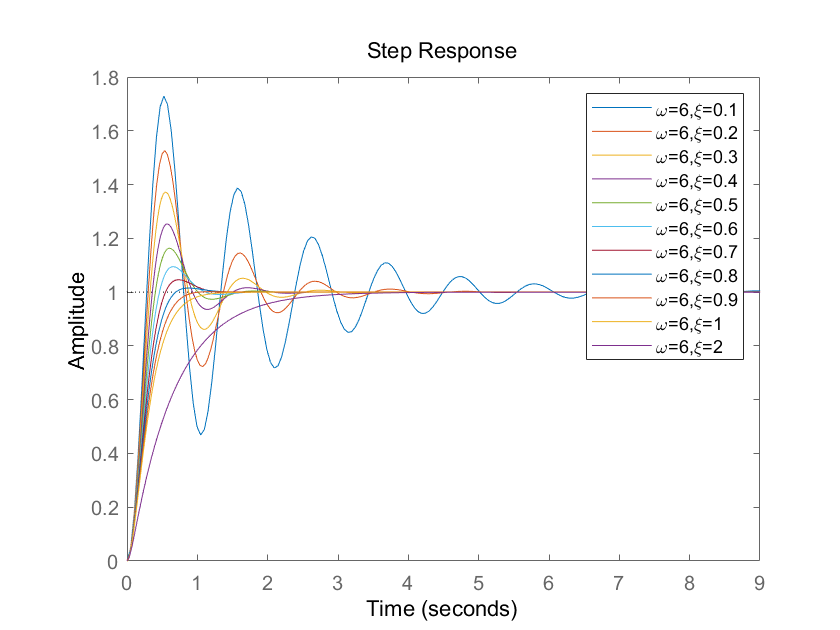

le = [];
x = '\omega=6,\xi=';
hold on
for kos=kesai
    num = Wn^2;
    den = [1,2*kos*Wn,Wn^2];
    step(num,den);
    
    num2str(kos);
    y = [x,num2str(kos)];
    le = [le,string(y)];
    
end
legend(le)
hold off

## 例2.2：绘制出当ξ=0.7， ωn取2，4，6，8，10，12 时的单位阶跃响应

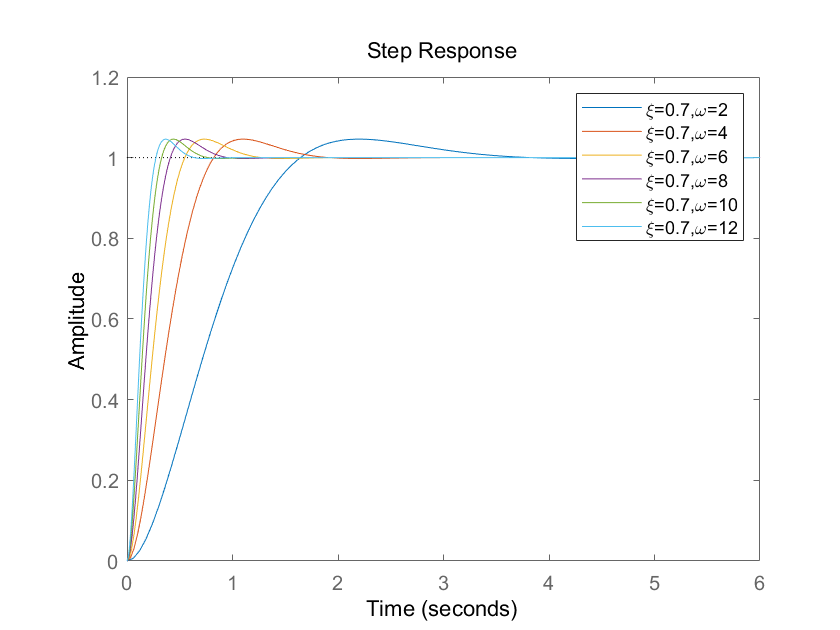


clear
clc
clf

le = [];
x = '\xi=0.7,\omega=';
w = [2:2:12];
kesai = 0.7;
hold on
for Wn = w
    num = Wn^2;
    den = [1,2*kesai*Wn,Wn^2];
    step(num,den,6)
    
    num2str(Wn);
    y = [x,num2str(Wn)];
    le = [le,string(y)];
    
end
legend(le)
hold off

## 例2.3：求三阶系统的单位阶跃响应

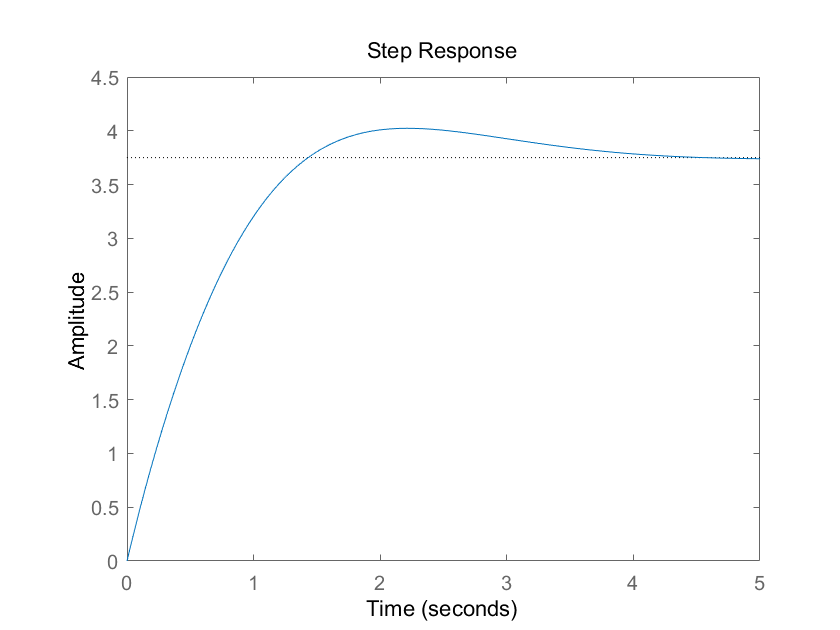


clear
clc
clf

num = [5 25 30];
den = [1 6 10 8];
step(num,den)

## 例2.4：当典型二阶系统中ξ=0.7，ωn =6 时的单位冲激响应


Wn =6;
kesai = 0.7

kesai = 0.7000

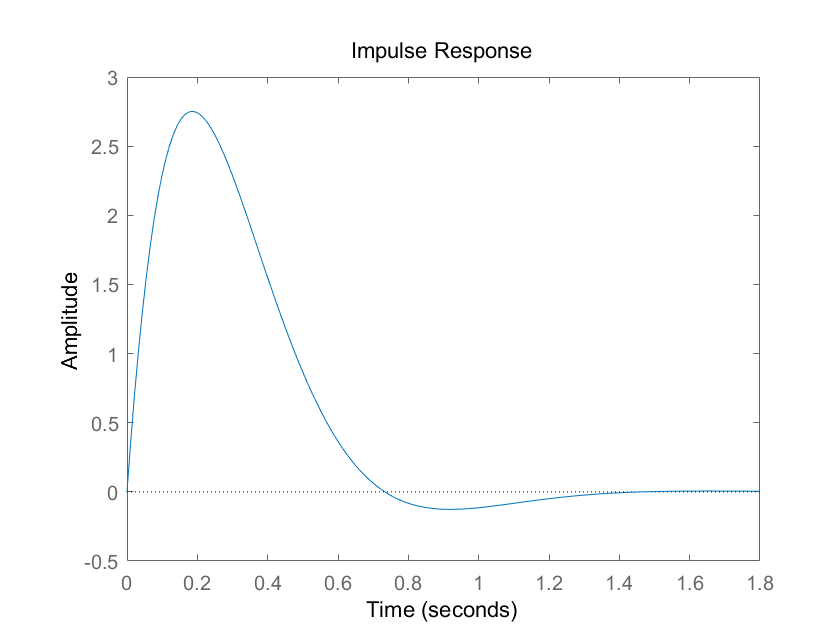

% hold on
num = Wn^2;
den = [1,2*kesai*Wn,Wn^2];
impulse(num,den)

% hold off




## 例2.5：单位阶跃响应，单位冲激响应及零输入响应（设初始状态x0=[1 1 1 -1]T）

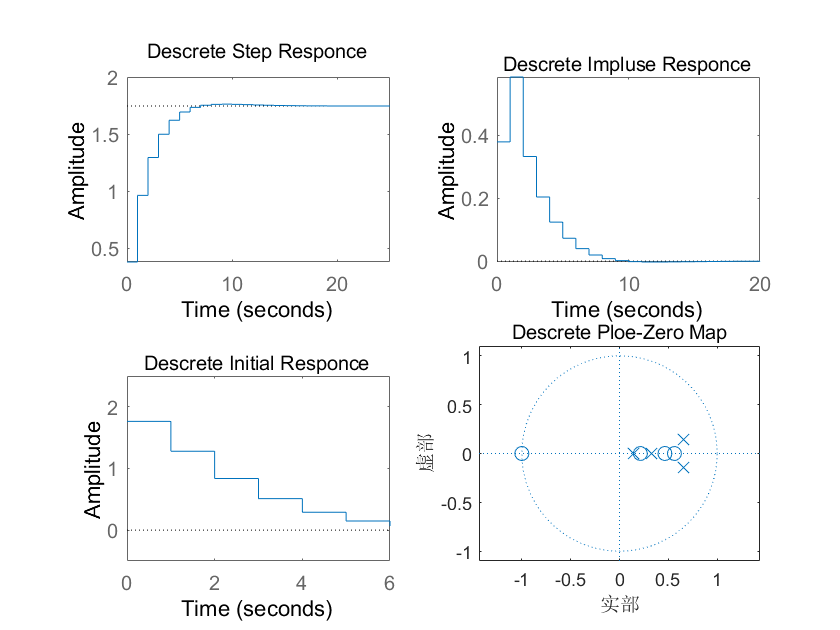


clear
clc
clf

a0=[-1.6,-0.9,0,0;0.9,0,0,0; 0.4,0.5,-5,-2.45;0,0,2.45,0];
b0=[1;0;1;0];
c0=[1,1,1,1];
d0=[0];
t=0.5;
[a,b,c,d]=c2dm(a0,b0,c0,d0,t,'tustin');
figure(3);
subplot(2,2,1);
dstep(a,b,c,d);
title('Descrete Step Responce');
subplot(2,2,2);
dimpulse(a,b,c,d);
title('Descrete Impluse Responce');
subplot(2,2,3);
x0=[1;1;1;-1];
dinitial(a,b,c,d,x0);
axis([0 6 -0.5 2.5]);
title('Descrete Initial Responce');
subplot(2,2,4);
[z,p,k]=ss2zp(a,b,c,d,1);
zplane(z,p);
title('Descrete Ploe-Zero Map');

## 例2.6：求多输入多输出系统的单位阶跃响应和单位冲激响应

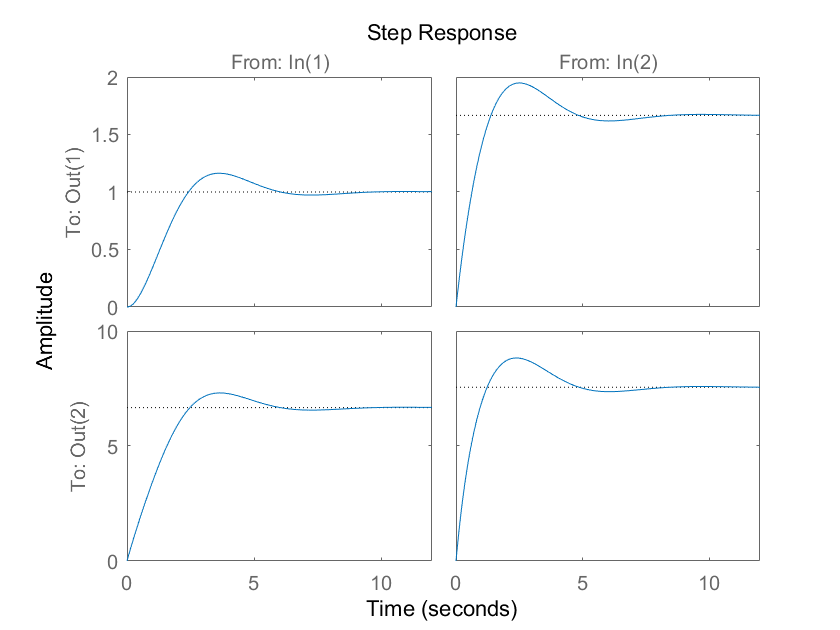


clf
a=[2.25 -5 -1.25 -0.5;2.25 -4.25 -1.25 -0.25;0.25 -0.5 -1.25 -1;1.25 -1.75 -0.25 -0.75];
b=[4 6;2 4;2 2;0 2];
c=[0 0 0 1;0 2 0 2];
d=zeros(2,2);
step(a,b,c,d);

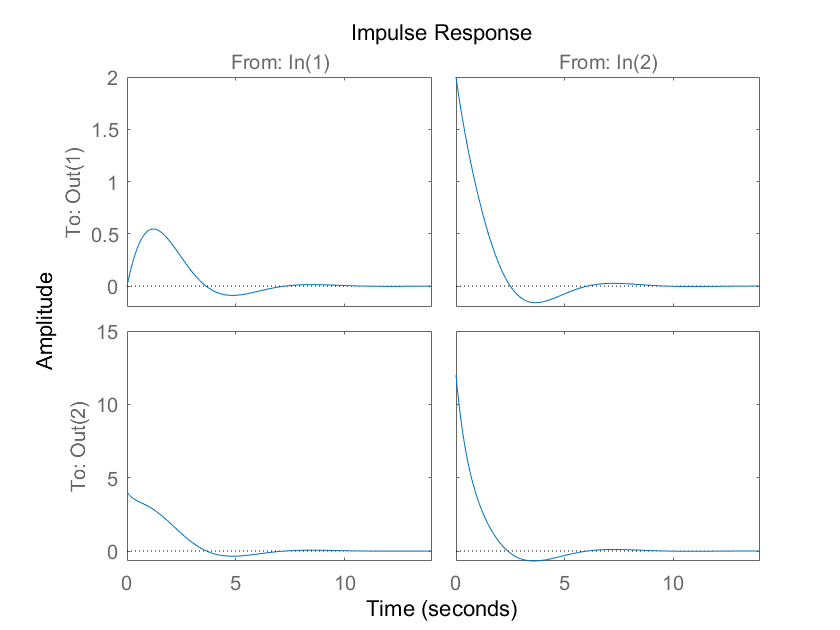

impulse(a,b,c,d);

## 例2.7：将例2.5 中的连续系统，以t=0.5 取样周期，采用双线性变换算法转换成离散系统，然后求出离散系统的单位阶跃响应、单位冲激响应及零输入响应（设初始状态x0=[1 1 1 -1]T）


clf

a=[-1.6 -0.9 0 0;0.9 0 0 0;0.4 0.5 -5 -2.45;0 0 2.45 0];
b=[1;0;1;0];
c=[1 1 1 1 ];
d=[0];
t=0.5;
sys = ss(a,b,c,d)

sys =
 
  A = 
          x1     x2     x3     x4
   x1   -1.6   -0.9      0      0
   x2    0.9      0      0      0
   x3    0.4    0.5     -5  -2.45
   x4      0      0   2.45      0
 
  B = 
       u1
   x1   1
   x2   0
   x3   1
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   1   1   1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sysd=c2d(sys,t,'tustin')

sysd =
 
  A = 
            x1       x2       x3       x4
   x1   0.3787  -0.3102        0        0
   x2   0.3102   0.9302        0        0
   x3  0.06729  0.08009  -0.2381  -0.4666
   x4  0.04122  0.04906   0.4666   0.7142
 
  B = 
            u1
   x1   0.3447
   x2  0.07755
   x3   0.2073
   x4    0.127
 
  C = 
           x1      x2      x3      x4
   y1  0.8987  0.8746  0.6142  0.6238
 
  D = 
           u1
   y1  0.3782
 
Sample time: 0.5 seconds
Discrete-time state-space model.



a = sysd.A

a = 4×4
    0.3787   -0.3102         0         0
    0.3102    0.9302         0         0
    0.0673    0.0801   -0.2381   -0.4666
    0.0412    0.0491    0.4666    0.7142


b = sysd.B

b = 4×1
    0.3447
    0.0776
    0.2073
    0.1270


c = sysd.C

c = 1×4
    0.8987    0.8746    0.6142    0.6238


d = sysd.D

d = 0.3782

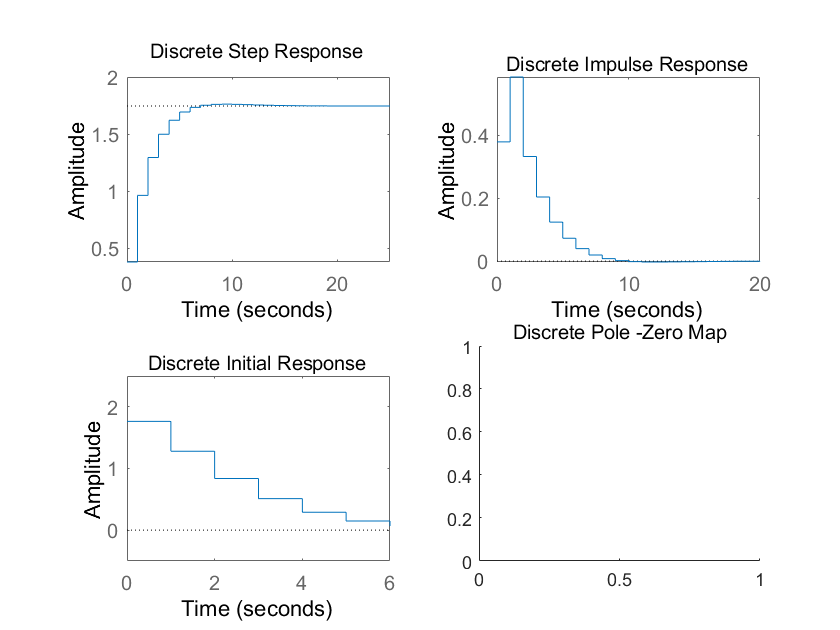

figure(1)
subplot(2,2,1);
dstep(a,b,c,d);
title('Discrete Step Response');
subplot(2,2,2);
dimpulse(a,b,c,d);
title('Discrete Impulse Response');
subplot(2,2,3);
x0=[1;1;1;-1];
dinitial(a,b,c,d,x0);
axis([0 6 -0.5 2.5]);
title('Discrete Initial Response');
subplot(2,2,4);
[z,p,k]=ss2zp(a,b,c,d,1);
title('Discrete Pole -Zero Map');

# **实验三．控制系统的根轨迹法**

## 例3.1：绘制出通过单位负反馈构成的闭环系统的根轨迹

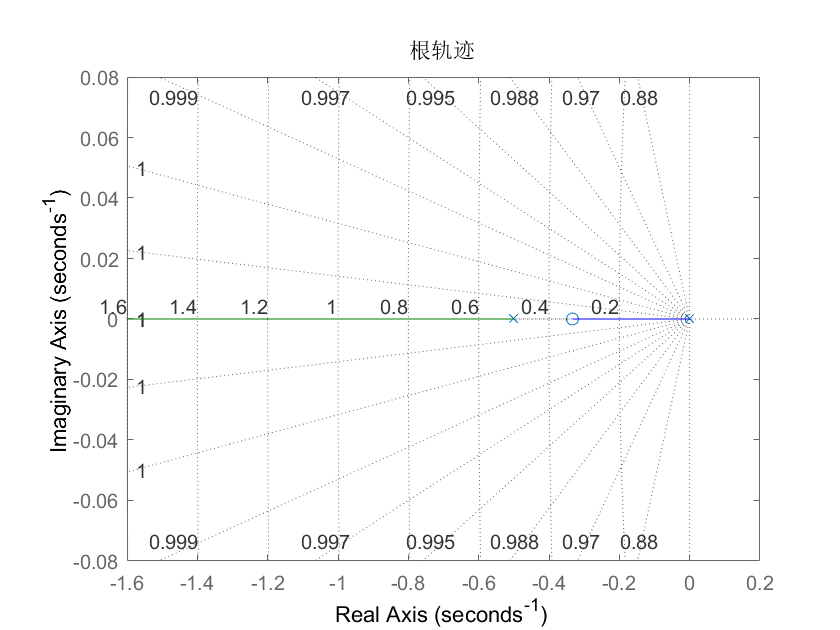


clear
clc
clf

num = [3 1];
den = [2 1 0];
rlocus(num,den)
sgrid
title('根轨迹')

## 例3.2：绘制出闭环系统的根轨迹，并确定交点处的增益 k


num=[1,5]

num = 1×2
     1     5


den=[1,5,6,0]

den = 1×4
     1     5     6     0


rlocus(num,den)
sgrid
title('根轨迹')
[k,p]=rlocfind(num,den)

Select a point in the graphics window


selected_point = -0.8744 - 0.0413i

k = 0.5081

p = 3×1
  -3.2274 + 0.0000i
  -0.8863 + 0.0397i
  -0.8863 - 0.0397i


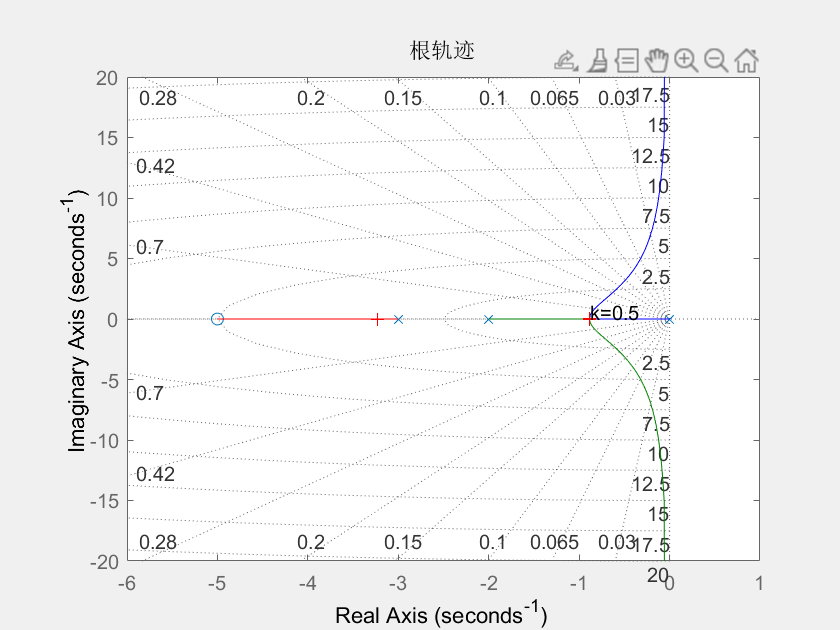

gtext('k=0.5')

## 例3.3：绘制出闭环系统的根轨迹

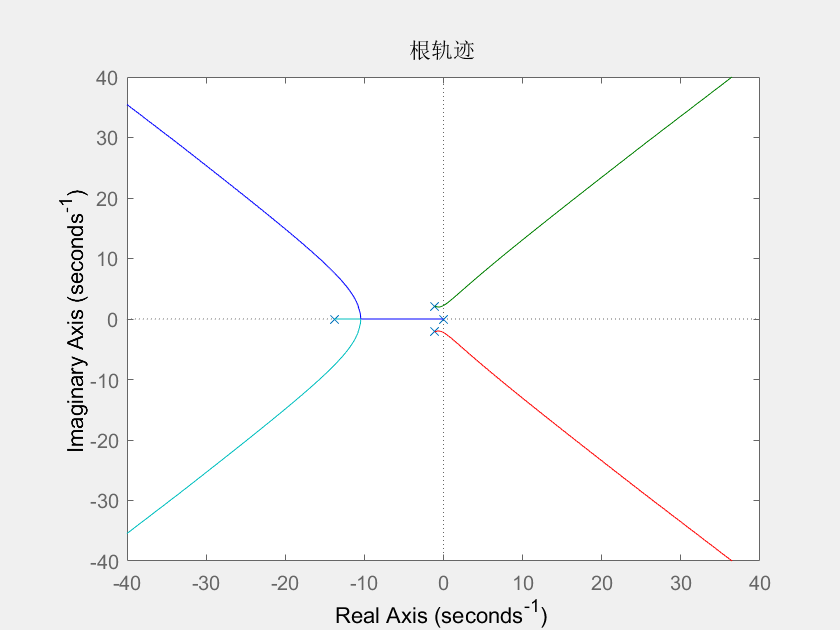


clear
clc
clf

num=[1];
den=[1,16,36,80,0];
rlocus(num,den)
title('根轨迹')

## 例3.4：绘制出闭环系统的根轨迹


num=[1,2]

num =      1     2


den=[1,4,3]

den =      1     4     3


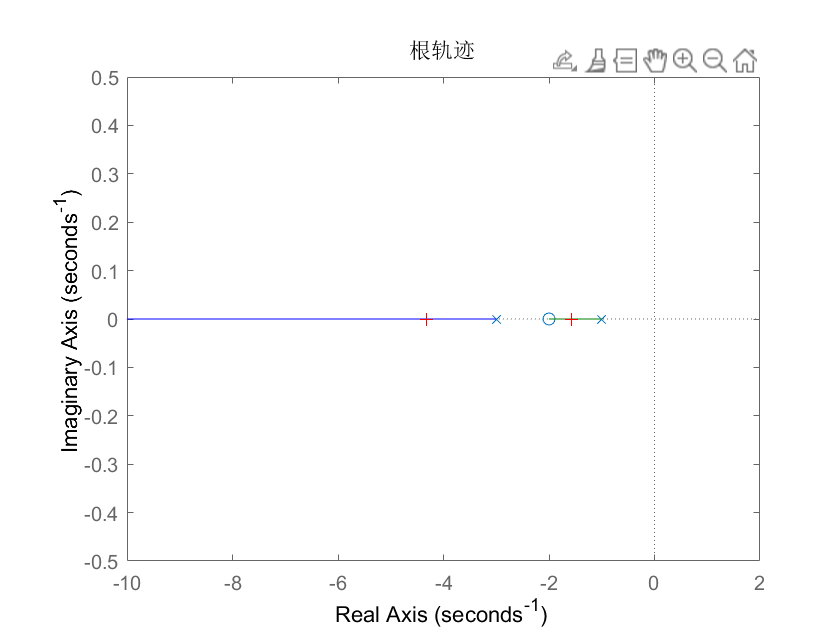

Select a point in the graphics window


selected_point = -4.3223 + 0.0010i

k = 1.8917

p =    -4.3223
   -1.5694


figure(1);
rlocus(num,den)
title('根轨迹')
[k,p]=rlocfind(num,den)

figure(2);
k=55;
num1=k*[1 2]

num1 =     55   110


den=[1 4 3]

den =      1     4     3


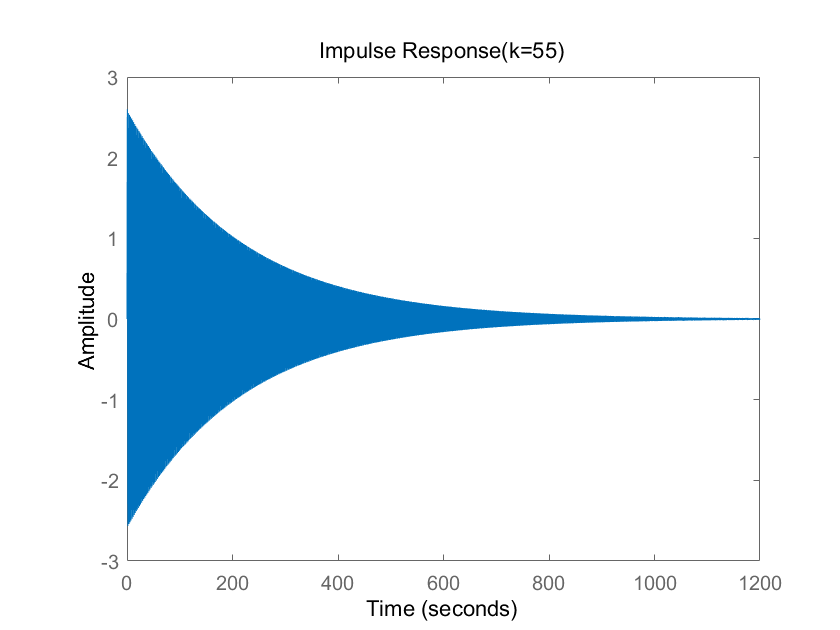

den1=conv(den,den);
[num,den]=cloop(num1,den1,-1);
impulse(num,den);
title('Impulse Response(k=55)')

figure(3);
k=56;
num1=k*[1 2]

num1 =     56   112


den=[1 4 3]

den =      1     4     3


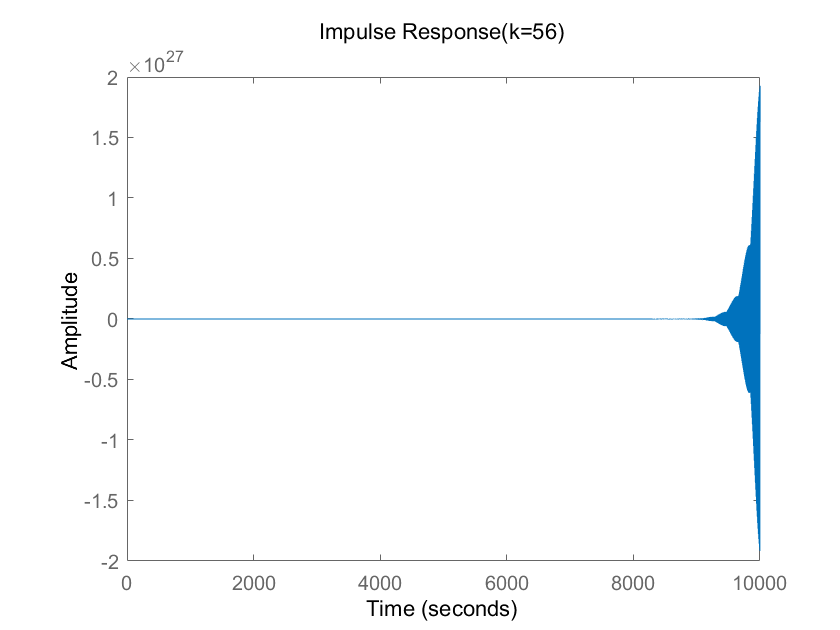

den1=conv(den,den);
[num,den]=cloop(num1,den1,-1);
impulse(num,den);
title('Impulse Response(k=56)')

# **实验四．控制系统反馈校正设计**

## 例4.1：设计反馈控制器


clear
clc
clf

disp('Pole Placement ⋯⋯ using transformation matrix')

Pole Placement ⋯⋯ using transformation matrix


a=[0 1 0;0 0 1;-6 -11 -6];
b=[0;0;10]

b =      0
     0
    10


cam=ctrb(a,b);
disp('Tha rank of controllability matrix');

Tha rank of controllability matrix


rc=rank(cam)

rc = 3

beta=poly(a)

beta =     1.0000    6.0000   11.0000    6.0000


a1=beta(2);a2=beta(3);a3=beta(4);
w=[a2 a1 1;a1 1 0;1 0 0];
t=cam*w;
j=[-2+2*sqrt(3)*i 0 0;0 -2-2*sqrt(3)*i 0;0 0 -10];
alph=poly(j);
aa1=alph(2);aa2=alph(3);aa3=alph(4);
k=[aa3-a3 aa2-a2 aa1-a1]*(inv(t))

k =    15.4000    4.5000    0.8000


disp('Pole Placement ⋯⋯ using Ackermann''s formula');

Pole Placement ⋯⋯ using Ackermann's formula


a=[0 1 0;0 0 1;-6 -11 -6];
b=[0;0;10];
cam=ctrb(a,b);
disp('The rank of controllability matrix');

The rank of controllability matrix


rc=rank(cam)

rc = 3

j=[-2+2*sqrt(3)*i 0 0;0 2-2*sqrt(3)*i 0;0 0 -10];
alph=poly(j);
phi=polyvalm(alph,a);
k=[0 0 1]*(inv(cam))*phi

k =    7.4000 +13.8564i  -0.3000 + 1.3856i   0.4000 + 0.0000i


p=[-2+2*sqrt(3)*i -2-2*sqrt(3)*i -10];
k=place(a,b,p)

k =    15.4000    4.5000    0.8000


## 例4.2：设计全阶状态观测器


a=[0 1 0;0 0 1;-6 -1 -6];
b=[0;0;1]

b =      0
     0
     1


c=[1 0 0]

c =      1     0     0


disp('The rank of obserbability matrix')

The rank of obserbability matrix


ro=rank(obsv(a,c))

ro = 3

a1=a';
b1=c';
c1=b';
p=[-2+2*sqrt(3)*i -2-2*sqrt(3)*i -5];
k=acker(a1,b1,p)

k =     3.0000   17.0000  -31.0000


ke=k'

ke =     3.0000
   17.0000
  -31.0000


## 例4.3：设计最小阶状态观测器


a=[0 1 0;0 0 1;-6 -11 -6];
b=[0;0;1];c=[1 0 0]

c =      1     0     0


aaa=[a(1,1)];aab=[a(1,2:3)];
aba=[a(2:3,1)];abb=[a(2:3,2:3)];
ba=b(1,1);bb=b(2:3,1);
a1=abb;c1=aab;
disp('Design of a minimum-order observer');

Design of a minimum-order observer


ro=rank(obsv(a1,c1))

ro = 2

ax=a1';
bx=c1';
p=[-2+2*sqrt(3)*i -2-2*sqrt(3)*i];
k=acker(ax,bx,p);
ke=k'

ke =     -2
    17
